% Tabula rasa
clear all; clc;


% Internal dynamics (pure double integrator)
n=2;
m=2;
Am = zeros(n,n);
Am(1,2) = 1;
Am(2,2) = 0;
% Am = [-1 0.5; -0.3 0.7];

% Input dynamics
Bm = zeros(n,m);
Bm(2,1) = 1;
Bm(2,2) = -1;

Q = 10*eye(n);
R = eye(m);

[L, P, ~]  = lqr(Am, Bm, Q, R);
P=eye(2)

P =      1     0
     0     1


% Define the dynamics
SAT_VAL = 5;
a = 2/SAT_VAL; % Sigmoid saturates at 2/a.
fprintf("Saturation value: %d\n", SAT_VAL);

Saturation value: 5


u = @(x) 2.*(1-exp(-a.*x))./(a.*(1+exp(-a.*x)));
dynamics = @(x) Am*x + Bm*u(L*(-x));
% dynamics = @(x) Am*x + Bm*L*(-x);


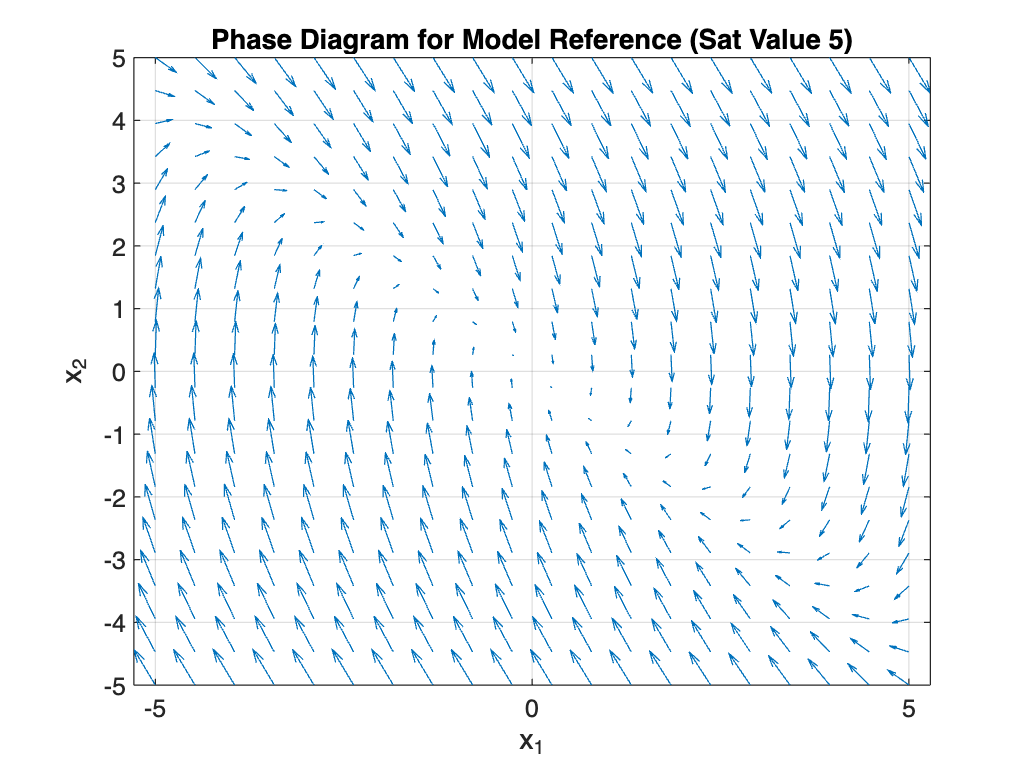

% Define the range of values for the phase diagram
x_range = linspace(-5, 5, 20); % Range for x1
y_range = linspace(-5, 5, 20); % Range for x2

% Create a grid for plotting
[X1, X2] = meshgrid(x_range, y_range);

% Compute the derivatives at each grid point
U = zeros(size(X1)); % dx1/dt
V = zeros(size(X2)); % dx2/dt
for i = 1:numel(X1)
    x = [X1(i); X2(i)]; % Current state vector
    dx = dynamics(x);   % Evaluate dynamics
    U(i) = dx(1);       % dx1/dt
    V(i) = dx(2);       % dx2/dt
end

% Normalize the vectors for better visualization
% M = sqrt(U.^2 + V.^2); % Vector lengths
% U = U ./ M; % Normalize x-component
% V = V ./ M; % Normalize y-component

% Plot the quiver plot
figure;
quiver(X1, X2, U, V); % Quiver plot for the vector field
xlabel('x_1');
ylabel('x_2');
title(['Phase Diagram for Model Reference (Sat Value ', num2str(SAT_VAL), ')']);
axis tight;
hold on

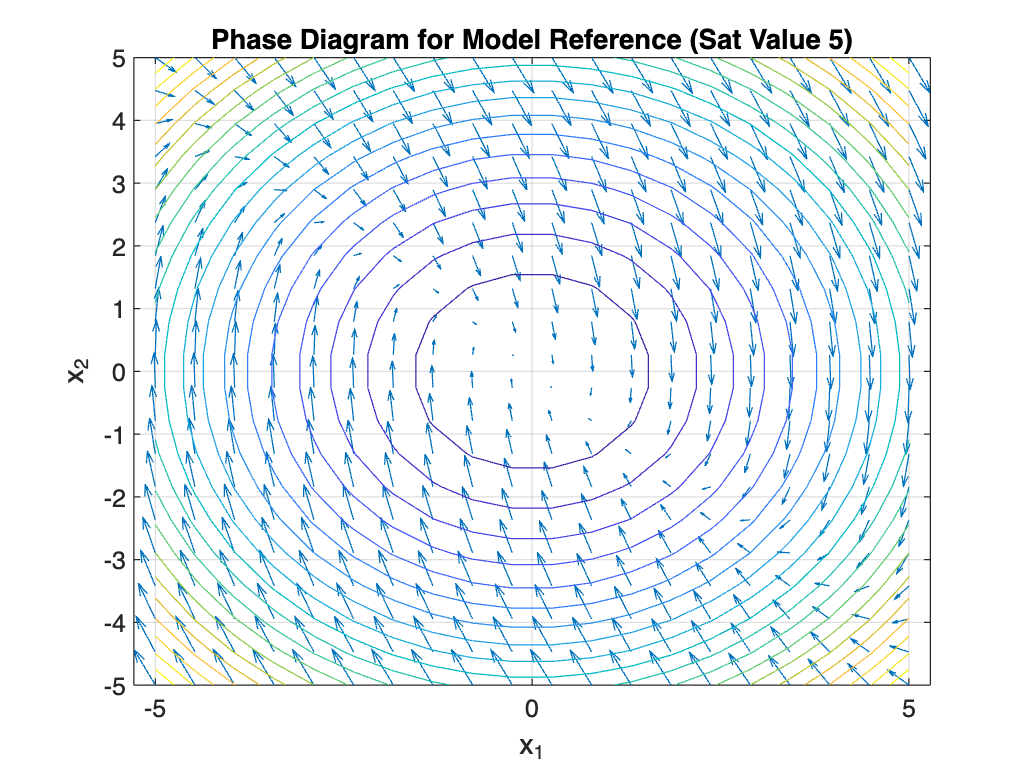

% Compute time derivative of Lyapunov function
% Lyapunov function V(x) = x'Px
% P is already computed from LQR

% Function to compute V(x) and its derivative along trajectories
lyapunov = @(x) x' * P * x; % Lyapunov function
lyapunov_dot = @(x) 2 * x' * P * dynamics(x); % Time derivative of Lyapunov function

% Evaluate the Lyapunov function and its derivative on the grid
V_values = zeros(size(X1)); % Values of V(x)
dV_values = zeros(size(X1)); % Values of dV/dt

for i = 1:numel(X1)
    x = [X1(i); X2(i)];
    V_values(i) = lyapunov(x); % Evaluate V(x)
    dV_values(i) = lyapunov_dot(x); % Evaluate dV/dt
end

% % Plot Lyapunov function
% contour(X1, X2, V_values, 20); % Contour plot of V(x)
% xlabel('x_1');
% ylabel('x_2');
% title('Lyapunov Function V(x) = x^T P x');
% grid on;
% hold off


% Plot the derivative of the Lyapunov function
contour(X1, X2, V_values, 20); % Contour plot of dV/dt
xlabel('x_1');
ylabel('x_2');
grid on;
hold off;